syms q
G = (q-1)*(q+.9)/(q^2-1.4*q+.5)

$$G = \frac{\left(q-1\right)\,\left(q+\frac{9}{10}\right)}{q^{2}-\frac{7\,q}{5}+\frac{1}{2}}$$

H = (q-.1)/(q-.9)

$$H = \frac{q-\frac{1}{10}}{q-\frac{9}{10}}$$

syms u y
r = collect(H^-1*G*u + (1-H^-1) * (H^-1*G*u + (1-H^-1)*y),q)

$$r = \frac{\left(1000\,u\right)\,q^{4}+\left(-300\,u\right)\,q^{3}+\left(640\,y-1510\,u\right)\,q^{2}+\left(243\,u-896\,y\right)\,q+567\,u+320\,y}{1000\,q^{4}-1600\,q^{3}+790\,q^{2}-114\,q+5}$$

num = collect(numden(r),[u,y])

$$num = \left(1000\,q^{4}-300\,q^{3}-1510\,q^{2}+243\,q+567\right)\,u+\left(640\,q^{2}-896\,q+320\right)\,y$$

syms u y
s = collect(G*u + (1 - (1 + 0.8*q^-1)*H^-1)*(y - G*u),q)

$$s = \frac{\left(500\,u\right)\,q^{4}+\left(-100\,u\right)\,q^{3}+\left(360\,y-805\,u\right)\,q^{2}+\left(81\,u-504\,y\right)\,q+324\,u+180\,y}{500\,q^{4}-750\,q^{3}+320\,q^{2}-25\,q}$$

num = collect(numden(s),[u,y])

$$num = \left(-500\,q^{4}+100\,q^{3}+805\,q^{2}-81\,q-324\right)\,u+\left(-360\,q^{2}+504\,q-180\right)\,y$$

collect((H - 1 - 0.8/q))

$$ans = \frac{36}{50\,q^{2}-45\,q}$$

syms c
collect((H - 1 - 0.8/(q-0.1)))

$$ans = \frac{64}{100\,q^{2}-100\,q+9}$$

clf
Htf = tf([1 -0.1],[1 -0.9],1)

Htf =
 
  z - 0.1
  -------
  z - 0.9
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


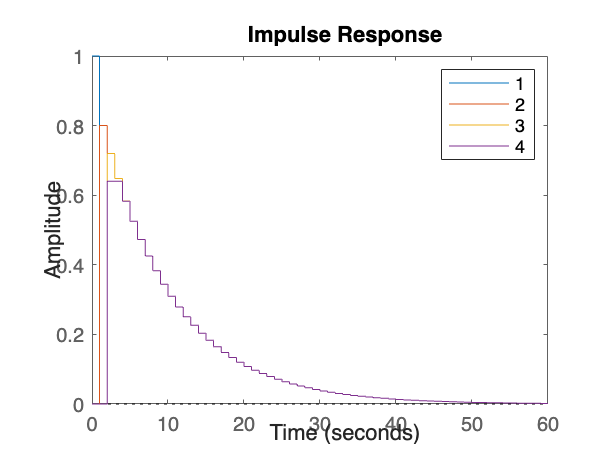

impulse(Htf)
hold on
impulse(Htf-1)
impulse(Htf - 1 - tf(0.8,[1 0],1))
impulse(Htf - 1 - tf(0.8,[1 -0.1],1))
legend('1','2','3','4')

shg